## Generate noisy signal - fixed amount of samples

amplitude = 0.625;
shift = 5.5 ;
width = 0.1;
offset = 0.7;

% SNR = amplitude / std_dev(edge) [or better std_Dev(ampltiude) / std_dev(edge)]
SNR = 20 ;% [15:1:25] ;

n_samples = 100;
repet = 100 ;

sp_result.x = [] ;
sp_result.a.y = [];
sp_result.a.dev = [];

sp_result.width.y = [];
sp_result.width.dev = [];

sp_result.shift.y = [];
sp_result.shift.dev = [];

sp_result.offset.y = [];
sp_result.offset.dev = [];

show_plot = false ;
for range=0.05:0.05:2
    x_end = shift + range;
    x_start = shift - range;

    error_a_raw = [] ;
    error_width_raw = [] ;
    error_shift_raw = [] ;
    error_offset_raw = [] ;
    for i=1:repet
        [data_X, data_Y, fitted, error_a, error_width, error_shift, error_offset] =...
            fit_on_noisy_lorentzian_detailled(n_samples, x_end, x_start, amplitude, width, shift, offset, SNR, show_plot);
        error_a_raw = [error_a_raw error_a] ;
        error_width_raw = [error_width_raw error_width] ;
        error_shift_raw = [error_shift_raw error_shift] ;
        error_offset_raw = [error_offset_raw error_offset] ;
    end
    sp_result.x = [sp_result.x (x_end - x_start)];
    
    sp_result.a.y = [sp_result.a.y mean(error_a_raw)];
    sp_result.a.dev = [sp_result.a.dev std(error_a_raw)];

    sp_result.width.y = [sp_result.width.y mean(error_width_raw)];
    sp_result.width.dev = [sp_result.width.dev std(error_width_raw)];

    sp_result.shift.y = [sp_result.shift.y mean(error_shift_raw)];
    sp_result.shift.dev = [sp_result.shift.dev std(error_shift_raw)];

    sp_result.offset.y = [sp_result.offset.y mean(error_offset_raw)];
    sp_result.offset.dev = [sp_result.offset.dev std(error_offset_raw)];
end



L_description = ["L : amplitude = " + num2str(amplitude) ...
    + ", shift = " + num2str(shift) ...
    + ", width = " + num2str(width) ];

simu_description = "number sample = " + num2str(n_samples) + ", repetition = " + num2str(repet) + ", SNR = " + num2str(SNR) ;

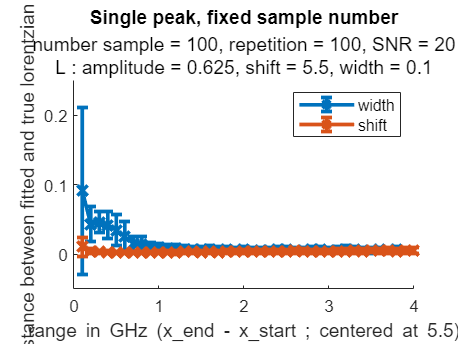


clf
hold on
%plot(result.x, result.y)
% errorbar(sp_result.x, sp_result.a.y, sp_result.a.dev, 'x-', "DisplayName", "Amplitude")
errorbar(sp_result.x, sp_result.width.y, sp_result.width.dev, 'x-', "DisplayName", "width",'MarkerSize', 8, 'LineWidth', 2)
errorbar(sp_result.x, sp_result.shift.y, sp_result.shift.dev, 'x-', "DisplayName", "shift",'MarkerSize', 8, 'LineWidth', 2)
% errorbar(sp_result.x, sp_result.offset.y, sp_result.offset.dev, 'x-', "DisplayName", "offset")
% plot(sp_result.x, sp_result.a.y+ sp_result.width.y + sp_result.shift.y + sp_result.offset.y,'.-', "DisplayName", "sum")
title("Single peak, fixed sample number")
subtitle([simu_description; L_description]) ;
ylabel("Distance between fitted and true lorentzian")
xlabel("range in GHz (x\_end - x\_start ; centered at "+ shift +")") ;
legend ;

## Generate noisy signal - Double peak, fixed number of samples


L1_amplitude = 0.625;
L1_shift = 5 ;
L1_width = 0.1;

L2_amplitude = 0.5;
L2_shift = 5.4 ;
L2_width = 0.1;

offset = 0.7;

% SNR = amplitude / std_dev(edge) [or better std_Dev(ampltiude) / std_dev(edge)]
SNR = 20 ;% [15:1:25] ;

sample_number = 100;
repet = 100 ;

dp_density_result.x = [] ;
dp_density_result.y = [] ;
dp_density_result.dev = [];

mean_val.L1.amplitude  = [];
mean_val.L1.width      = [];
mean_val.L1.shift      = [];
mean_val.L1.total      = [];
mean_val.L2.amplitude  = [];
mean_val.L2.width      = [];
mean_val.L2.shift      = [];
mean_val.L2.total      = [];
mean_val.offset        = [];
mean_val.total         = [];

std_val.L1.amplitude  = [];
std_val.L1.width      = [];
std_val.L1.shift      = [];
std_val.L1.total      = [];
std_val.L2.amplitude  = [];
std_val.L2.width      = [];
std_val.L2.shift      = [];
std_val.L2.total      = [];
std_val.offset        = [];
std_val.total         = [];

show_plot = false ;
for range=0.05:0.05:2
    x_end = (L1_shift + L2_shift)/2  + range;
    x_start = (L1_shift + L2_shift)/2  - range;

    error_raw_L1_amplitude   = [] ;
    error_raw_L1_width       = [] ;
    error_raw_L1_shift       = [] ;
    error_raw_L1_total       = [] ;
    error_raw_L2_amplitude   = [] ;
    error_raw_L2_width       = [] ;
    error_raw_L2_shift       = [] ;
    error_raw_L2_total       = [] ;
    error_raw_offset         = [] ;
    error_raw_total          = [] ;

    for i=1:repet
        [data_X, data_Y, fitted, error] = fit_on_noisy_double_lorentzian_sample_number(...
            sample_number, x_end, x_start, ...
            L1_amplitude, L1_width, L1_shift,...
            L2_amplitude, L2_width, L2_shift, offset, SNR, show_plot);
        
        error_raw_L1_amplitude(end+1)   = error.L1.amplitude ;
        error_raw_L1_width(end+1)       = error.L1.width ;
        error_raw_L1_shift(end+1)       = error.L1.shift ;
        error_raw_L1_total(end+1)       = error.L1.total ;
        error_raw_L2_amplitude(end+1)   = error.L2.amplitude ;
        error_raw_L2_width(end+1)       = error.L2.width ;
        error_raw_L2_shift(end+1)       = error.L2.shift ;
        error_raw_L2_total(end+1)       = error.L2.total ;
        error_raw_offset(end+1)         = error.offset ;
        error_raw_total(end+1)          = error.total ;
    end
    dp_density_result.x = [dp_density_result.x (x_end - x_start)];
    %dp_density_result.y = [dp_density_result.y mean(error_raw)];
    %dp_density_result.dev = [dp_density_result.dev std(error_raw)];

    mean_val.L1.amplitude(end+1)  = mean(error_raw_L1_amplitude);
    mean_val.L1.width(end+1)      = mean(error_raw_L1_width );
    mean_val.L1.shift(end+1)      = mean(error_raw_L1_shift   );
    mean_val.L1.total(end+1)      = mean(error_raw_L1_total   );
    mean_val.L2.amplitude(end+1)  = mean(error_raw_L2_amplitude);
    mean_val.L2.width(end+1)      = mean(error_raw_L2_width  );
    mean_val.L2.shift(end+1)      = mean(error_raw_L2_shift  );
    mean_val.L2.total(end+1)      = mean(error_raw_L2_total  );
    mean_val.offset(end+1)        = mean(error_raw_offset      );
    mean_val.total(end+1)         = mean(error_raw_total       );

    std_val.L1.amplitude(end+1)  = std(error_raw_L1_amplitude);
    std_val.L1.width(end+1)      = std(error_raw_L1_width );
    std_val.L1.shift(end+1)      = std(error_raw_L1_shift   );
    std_val.L1.total(end+1)      = std(error_raw_L1_total   );
    std_val.L2.amplitude(end+1)  = std(error_raw_L2_amplitude);
    std_val.L2.width(end+1)      = std(error_raw_L2_width  );
    std_val.L2.shift(end+1)      = std(error_raw_L2_shift  );
    std_val.L2.total(end+1)      = std(error_raw_L2_total  );
    std_val.offset(end+1)        = std(error_raw_offset      );
    std_val.total(end+1)         = std(error_raw_total       );
end

L1_L2_description = ["L1 : amplitude = " + num2str(L1_amplitude) ...
    + ", shift = " + num2str(L1_shift) ...
    + ", width = " + num2str(L1_width) ...
    ; ...
    "L2 : amplitude = " + num2str(L2_amplitude) ...
    + ", shift = " + num2str(L2_shift) ...
    + ", width = " + num2str(L2_width) ];

simu_description = "sample number = " + num2str(sample_number) + ", repetition = " + num2str(repet) + ", SNR = " + num2str(SNR) ;

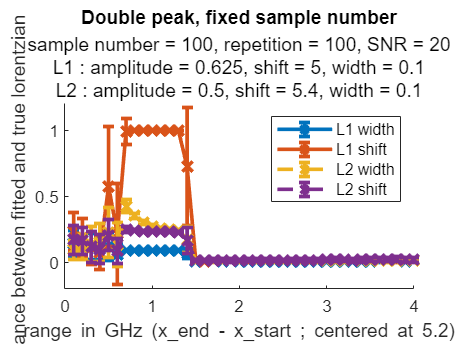


clf
hold on
%plot(result.x, result.y)
%errorbar(dp_density_result.x, dp_density_result.y, dp_density_result.dev, 'x-')
x = dp_density_result.x ;
% errorbar(x , mean_val.L1.amplitude, std_val.L1.amplitude, 'x-', "DisplayName", "L1 amplitude");
errorbar(x , mean_val.L1.width, std_val.L1.width, 'x-', "DisplayName", "L1 width",'MarkerSize', 8, 'LineWidth', 2);
errorbar(x , mean_val.L1.shift, std_val.L1.shift, 'x-', "DisplayName", "L1 shift",'MarkerSize', 8, 'LineWidth', 2);
% errorbar(x , mean_val.L1.total, std_val.L1.total, '-', "DisplayName", "L1 total");

% errorbar(x , mean_val.L2.amplitude, std_val.L2.amplitude, 'x--', "DisplayName", "L2 amplitude");
errorbar(x , mean_val.L2.width, std_val.L2.width, 'x--', "DisplayName", "L2 width",'MarkerSize', 8, 'LineWidth', 2);
errorbar(x , mean_val.L2.shift, std_val.L2.shift, 'x--', "DisplayName", "L2 shift",'MarkerSize', 8, 'LineWidth', 2);
% errorbar(x , mean_val.L2.total, std_val.L2.total, '-', "DisplayName", "L2 total");

% errorbar(x , mean_val.offset, std_val.offset, '.-', "DisplayName", "offset");
% errorbar(x , mean_val.total, std_val.total, '-', "DisplayName", "total");

title("Double peak, fixed sample number")
subtitle([simu_description; L1_L2_description]) ;
ylabel("Distance between fitted and true lorentzian")
xlabel("range in GHz (x\_end - x\_start ; centered at "+ (L1_shift + L2_shift)/2 +")") ;
legend

function [fitted, fit_gof] = fit_lorentzian_cpu(data_X, data_Y, show_plot)
    SinglePerfectPeak  = fittype('a * b / (b + (c - x) ^2) + s') ;
    options = fitoptions(SinglePerfectPeak);
    options.StartPoint = [1 0.3 5.3 ...
        mean(data_Y) ] ;
    options.Lower = [0.05 0.05 5 ...
        0.4];
    options.Upper = [2 0.5 6 ...
        1];
    
    [fitted, fit_gof] = fit(data_X, data_Y, SinglePerfectPeak, options);
    if(show_plot)
        clf
        hold on
        plot(data_X, data_Y);
        plot(data_X, fitted(data_X));
    end
end

function [fitted, fit_gof] = fit_double_lorentzian_cpu(data_X, data_Y, show_plot)
    DoublePerfectPeak  = fittype('a1 * b1 / (b1 + (c1 - x) ^2) + a2 * b2 / (b2 + (c2 - x) ^2) + s') ;
    options = fitoptions(DoublePerfectPeak);
    options.StartPoint =[ ...
        1 1 ...
        0.5 0.5 ...
        4.8 5.3 ...
        mean(data_Y) ] ;
    options.Lower = [ ...
        0.1 0.1 ...
        0.01 0.01 ...
        4 4 ...
        0.5 ] ;
    options.Upper = [ ...
        2 2 ...
        0.6 0.6 ...
        6 6 ...
        2 ] ;
    
    [fitted, fit_gof] = fit(data_X, data_Y, DoublePerfectPeak, options);

    if(show_plot)
        clf
        hold on
        plot(data_X, data_Y);
        plot(data_X, fitted(data_X));

        plot(data_X, fitted.a1 .* fitted.b1 ./ (fitted.b1 + (fitted.c1 - data_X) .^2) + fitted.s) ;
        plot(data_X, fitted.a2 .* fitted.b2 ./ (fitted.b2 + (fitted.c2 - data_X) .^2) + fitted.s) ;
    end
end

function [data_X, data_Y, fitted, error] = fit_on_noisy_lorentzian(n_samples, x_end, x_start, amplitude, width, shift, offset, SNR, show_plot)
    data_X = (((1:n_samples)*(x_end - x_start) / n_samples ) + x_start)';
    data_Y =  amplitude .* width ./ (width + (data_X(:) - shift).^2 ) + offset ;
    
    noise = amplitude ./ SNR ;
    data_Y =  data_Y + noise * randn(size(data_Y)) ;
    [fitted, fitted_gof] = fit_lorentzian_cpu(data_X, data_Y, show_plot);
    
    error = sqrt((fitted.a - amplitude) ^2 ...
        + (fitted.b - width)^2 ...
        + (fitted.c - shift)^2 ...
        + (fitted.s - offset)^2) ;
end

function [data_X, data_Y, fitted, error_a, error_width, error_shift, error_offset] =...
    fit_on_noisy_lorentzian_detailled(n_samples, x_end, x_start, amplitude, width, shift, offset, SNR, show_plot)
    data_X = (((1:n_samples)*(x_end - x_start) / n_samples ) + x_start)';
    data_Y =  amplitude .* width ./ (width + (data_X(:) - shift).^2 ) + offset ;
    
    noise = amplitude ./ SNR ;
    data_Y =  data_Y + noise * randn(size(data_Y)) ;
    [fitted, fitted_gof] = fit_lorentzian_cpu(data_X, data_Y, show_plot);

    error_a         = sqrt((fitted.a - amplitude)^2 );
    error_width     = sqrt((fitted.b - width    )^2) ;
    error_shift     = sqrt((fitted.c - shift    )^2) ;
    error_offset    = sqrt((fitted.s - offset   )^2) ;

end

function [data_X, data_Y, fitted, error] = fit_on_noisy_lorentzian_sample_density(range_step, x_end, x_start, amplitude, width, shift, offset, SNR, show_plot)
    data_X = (x_start:range_step:x_end)';
    data_Y =  amplitude .* width ./ (width + (data_X(:) - shift).^2 ) + offset ;
    
    noise = amplitude ./ SNR ;
    data_Y =  data_Y + noise * randn(size(data_Y)) ;
    [fitted, fitted_gof] = fit_lorentzian_cpu(data_X, data_Y, show_plot);
    
    error = sqrt((fitted.a - amplitude) ^2 ...
        + (fitted.b - width)^2 ...
        + (fitted.c - shift)^2 ...
        + (fitted.s - offset)^2) ;

    %error = abs(fitted.c - shift) ;
end


function [data_X, data_Y, fitted, error] = fit_on_noisy_double_lorentzian_sample_density(range_step, x_end, x_start, ...
    L1_amplitude, L1_width, L1_shift,...
    L2_amplitude, L2_width, L2_shift, offset, SNR, show_plot)
    data_X = (x_start:range_step:x_end)';
    L1 =  L1_amplitude .* L1_width ./ (L1_width + (data_X(:) - L1_shift).^2 ) ;
    L2 =  L2_amplitude .* L2_width ./ (L2_width + (data_X(:) - L2_shift).^2 ) ;
    data_Y = L1 + L2 + offset ;

    noise = max(L1_amplitude, L2_amplitude) ./ SNR ;
    data_Y =  data_Y + noise * randn(size(data_Y)) ;
    [fitted, fitted_gof] = fit_double_lorentzian_cpu(data_X, data_Y, show_plot);
   
    error_1 = sqrt((fitted.a1 - L1_amplitude) ^2 ...
        + (fitted.b1 - L1_width)^2 ...
        + (fitted.c1 - L1_shift)^2 ...
        + (fitted.a2 - L2_amplitude) ^2 ...
        + (fitted.b2 - L2_width)^2 ...
        + (fitted.c2 - L2_shift)^2 ...
        + (fitted.s - offset)^2) ;

    error_2 = sqrt((fitted.a1 - L2_amplitude) ^2 ...
        + (fitted.b1 - L2_width)^2 ...
        + (fitted.c1 - L2_shift)^2 ...
        + (fitted.a2 - L1_amplitude) ^2 ...
        + (fitted.b2 - L1_width)^2 ...
        + (fitted.c2 - L1_shift)^2 ...
        + (fitted.s - offset)^2) ;

    error = min(error_1, error_2) ;
end




function [data_X, data_Y, fitted, error] = fit_on_noisy_double_lorentzian_sample_number(sample_number, x_end, x_start, ...
    L1_amplitude, L1_width, L1_shift,...
    L2_amplitude, L2_width, L2_shift, offset, SNR, show_plot)
    data_X = (((1:sample_number)*(x_end - x_start) / sample_number ) + x_start)';
    L1 =  L1_amplitude .* L1_width ./ (L1_width + (data_X(:) - L1_shift).^2 ) ;
    L2 =  L2_amplitude .* L2_width ./ (L2_width + (data_X(:) - L2_shift).^2 ) ;
    data_Y = L1 + L2 + offset ;

    noise = max(L1_amplitude, L2_amplitude) ./ SNR ;
    data_Y =  data_Y + noise * randn(size(data_Y)) ;
    [fitted, fitted_gof] = fit_double_lorentzian_cpu(data_X, data_Y, show_plot);


    if(fitted.c1 < fitted.c2) % fit1 => L1
        error.L1.amplitude  = abs(fitted.a1 - L1_amplitude);
        error.L1.width      = abs(fitted.b1 - L1_width);
        error.L1.shift      = abs(fitted.c1 - L1_shift);
        error.L1.total      = sqrt( ...
            (fitted.a1 - L1_amplitude)^2 + ...
            (fitted.b1 - L1_width)^2 + ...
            (fitted.c1 - L1_shift)^2);

        error.L2.amplitude  = abs(fitted.a2 - L2_amplitude);
        error.L2.width      = abs(fitted.b2 - L2_width);
        error.L2.shift      = abs(fitted.c2 - L2_shift);
        error.L2.total      = sqrt( ...
            (fitted.a2 - L2_amplitude)^2 + ...
            (fitted.b2 - L2_width)^2 + ...
            (fitted.c2 - L2_shift)^2);

        error.offset = abs(fitted.s - offset) ;
        error.total  = sqrt(...
            (fitted.a1 - L1_amplitude)^2 + ...
            (fitted.b1 - L1_width)^2 + ...
            (fitted.c1 - L1_shift)^2 + ...
            (fitted.a2 - L2_amplitude)^2 + ...
            (fitted.b2 - L2_width)^2 + ...
            (fitted.c2 - L2_shift)^2 + ...
            (fitted.s - offset) ^2);

    else %fit1 => L2
        error.L1.amplitude  = abs(fitted.a2 - L1_amplitude);
        error.L1.width      = abs(fitted.b2 - L1_width);
        error.L1.shift      = abs(fitted.c2 - L1_shift);
        error.L1.total      = sqrt( ...
            (fitted.a2 - L1_amplitude)^2 + ...
            (fitted.b2 - L1_width)^2 + ...
            (fitted.c2 - L1_shift)^2);

        error.L2.amplitude  = abs(fitted.a1 - L2_amplitude);
        error.L2.width      = abs(fitted.b1 - L2_width);
        error.L2.shift      = abs(fitted.c1 - L2_shift);
        error.L2.total      = sqrt( ...
            (fitted.a1 - L2_amplitude)^2 + ...
            (fitted.b1 - L2_width)^2 + ...
            (fitted.c1 - L2_shift)^2);

        error.offset = abs(fitted.s - offset) ;
        error.total  = sqrt(...
            (fitted.a2 - L1_amplitude)^2 + ...
            (fitted.b2 - L1_width)^2 + ...
            (fitted.c2 - L1_shift)^2 + ...
            (fitted.a1 - L2_amplitude)^2 + ...
            (fitted.b1 - L2_width)^2 + ...
            (fitted.c1 - L2_shift)^2 + ...
            (fitted.s - offset) ^2);
    end
end
